# Joint Lip Tongue 5-mechanism plus blood search

This is a sequential fitting approach.  It is applied to the full 500-700 nm range.

## Stage 1 (oeSolveJoint).

We fix a matrix with collagen1-smooth, FAD_webfluor, porphyrin and chlorophyll excitations. We choose these four because the first two fit the lip data well.  This guarantees that we will be able to find a fit to the lip data at the end.

We use oeSolveJoint to do two things.  

- Vary the blood oxygen of collagen, and 

- Search for one more, additional fluorophore, specified only as a skewed Gaussian with three parameters (mean, width, skew), to improve the fit. 

The additional (fifth) fluorophore is a stand-in for keratin, which is present on the tongue, but not on the lip.  We call this estimated fluorophore pseudo-keratin.

In the initial stage of the fit, we use the same blood density for all subjects.  The purpose of this stage is to learn about the parameters of the skewed Gaussian, which we store and use later.

## Stage 2 (oeSolveBlood)

We confirm that we can fit the lip data with just the collagen and FAD, searching for blood.  This is for the group lipData.

## Stage 3 (oeSolveBlood)

We loop through the subjects.  

For the tongue, we use the five fluorophores (collagen, FAD, porphyrin, chlorophyll, pseudo-keratin) and solve for the blood in each subject.

For the lip, we use only two fluorophores (collagen, FAD) and solve for the blood in each subject.

ieInit;
wave = 500:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
fise_plotDefaults;
subjects = {'Z','B','D','J'};
[T,dataDir] = oeDatabaseCreate;

## Load up the lip and tongue data

Here, we load all of the subjects into a single large data set for tongue and another one for lip.  In this case we group the 405 and 415 nm excitation lights.  We put the tongue and lip data, normalized at nWave, on the same graph.  We fit these to find the pseudo-keratin.

tongueData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    tongueData = cat(2,tongueData,tmp);
end

lipData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
    lipData = cat(2,lipData,tmp);
end 


tongueData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave); 
    tongueData450 = cat(2,tongueData450,tmp);
end

lipData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);       
    lipData450 = cat(2,lipData450,tmp);
end 


## Create the fixed fluorophores

The first two worked for the lip very well from 500-700nm (see s_oeBloodFluorophoreLipSrch700.mlx).  For the tongue, we add porphyrin and chlorophyl (see s_oeBloodFluorophoreTongueSrch700.mlx).

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor','PorphyrinBjurshammar','chlorophyllA-7'};
[fixedFluorophores,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## Call the joint search

We have fluorophores for the lip that we know can fit if we adjust the blood density for each subject.  Those are collagen1-smooth and FAD_webfluor.  Those are shown to work in s_oeBloodFluorophoreLipSrch700.mlx.

Here, we fix those two fluorophores and fit a first approximation to all the tongue data from all the subjects, getting an approximate extra skewed Gaussian and an overall blood density.  That fit includes porphyrin and chlorophyll.  We save that skewedGaussian as our one extra fluorophore, which we consider to be pseudo-keratin.  We will allow the blood density to vary using those five terms (collagen1-smooth, FAD_webfluor, porphyrin, chlorophyll, pseudo-keratin).  

We don't use the last three when we fit the lip. 

When we use it to fit the tongue data, we apply it to each subject separately to find the blood density for that subject.

[global_params, weights, finalFluorophores] = oeSolveJoint(wave, tongueData, fixedFluorophores);
disp(global_params)

   11.2290  425.0961  386.6748    5.0000



These are the original fluorophores without blood, and the newly derived pseudo-keratin fluorophore.  We use these later when we search for the blood density in individual subjects.  

savedFluorophores = [fixedFluorophores,finalFluorophores(:,end)];

## Show the fluorophores and blood incorporated

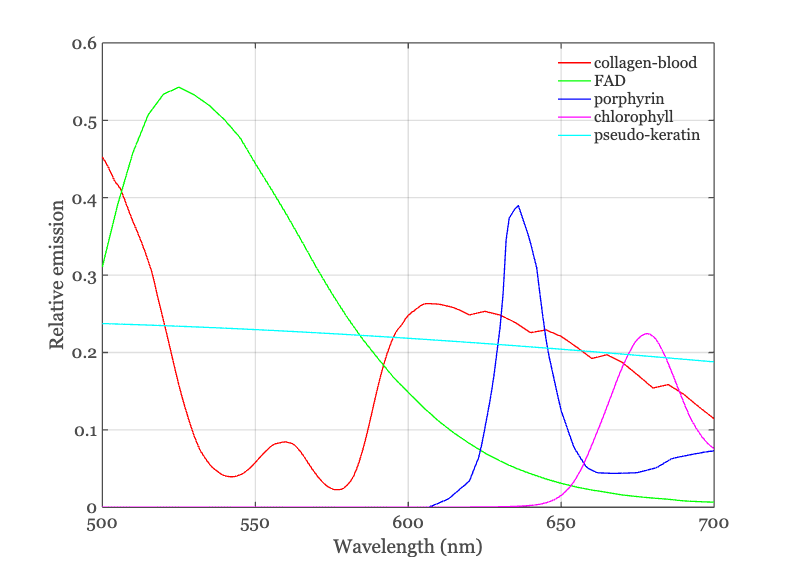

ieFigure;
plot(wave,finalFluorophores*diag(mean(weights,2)));
grid on; xlabel('Wavelength (nm)'); ylabel('Relative emission');
legend('collagen-blood','FAD','porphyrin','chlorophyll','pseudo-keratin');

## Show the predictions for the tongue data

These are the 405 nm and 415 nm fits.

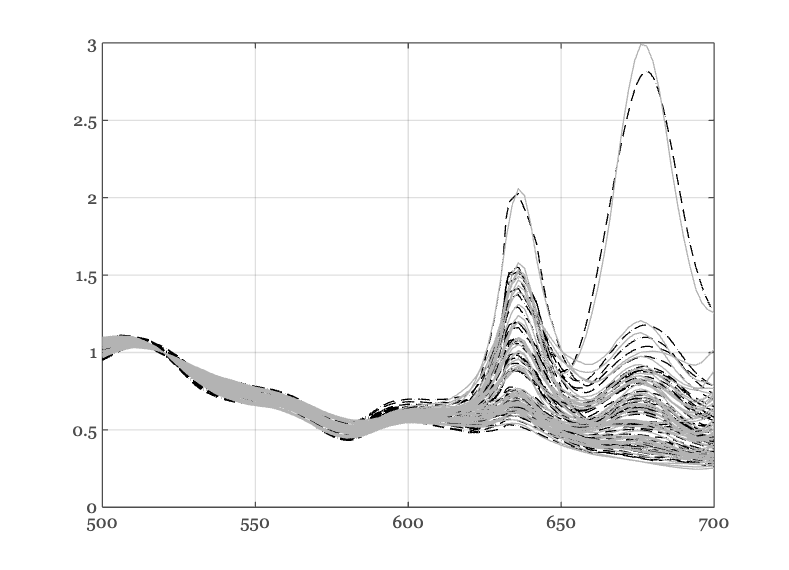

predicted = finalFluorophores*weights;
ieFigure; 
plot(wave,predicted,'k--'); hold on;
plot(wave,tongueData,'Color',[1 1 1]*0.7); grid on;

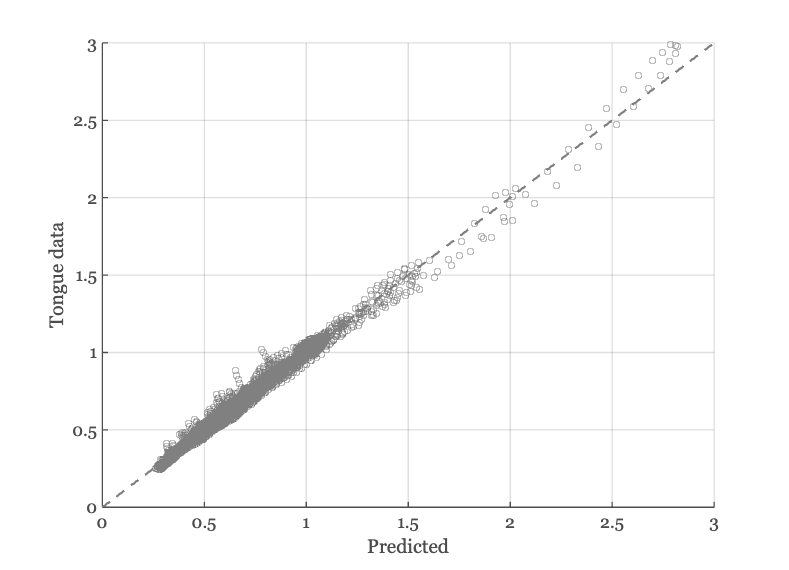

ieFigure;
hScatter = scatter(predicted(:),tongueData(:)); 
hScatter.CData = [1 1 1]*0.5;
xlabel('Predicted'); ylabel('Tongue data'); 
identityLine;

Here are the mean weights for the five different fluorophores when fit to the group tongue data.

mn = mean(weights,2);
fprintf('Collagen %.2f FAD %.2f Porphyrin %.2f Chlorophyll %0.2f PseudoKeratin %.2f\n',mn);

Collagen 10.43 FAD 0.54 Porphyrin 0.39 Chlorophyll 0.22 PseudoKeratin 0.30


## Fit the lip with a subset of fluorophores

We fit them using only the first two columns of the fixed fluorophores.  We just solve for the blood applied to the first column.  This step is not necessary, but it was a good check that we could approximate the group with a single blood optical density.

[od, weights,finalFluorophores] = oeSolveBlood(wave, lipData, fixedFluorophores(:,[1,2]));
fprintf('Blood density %.2f\n',od); ieFigure;

Blood density 8.63


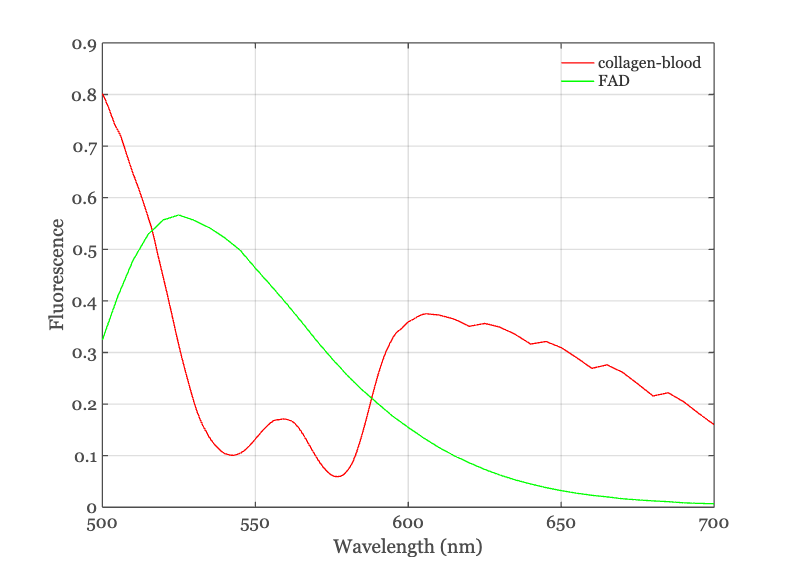

plot(wave,finalFluorophores*diag(mean(weights,2))); 
grid on; xlabel('Wavelength (nm)'); ylabel('Fluorescence');
legend('collagen-blood','FAD');

## Fits to lip 405 and 415

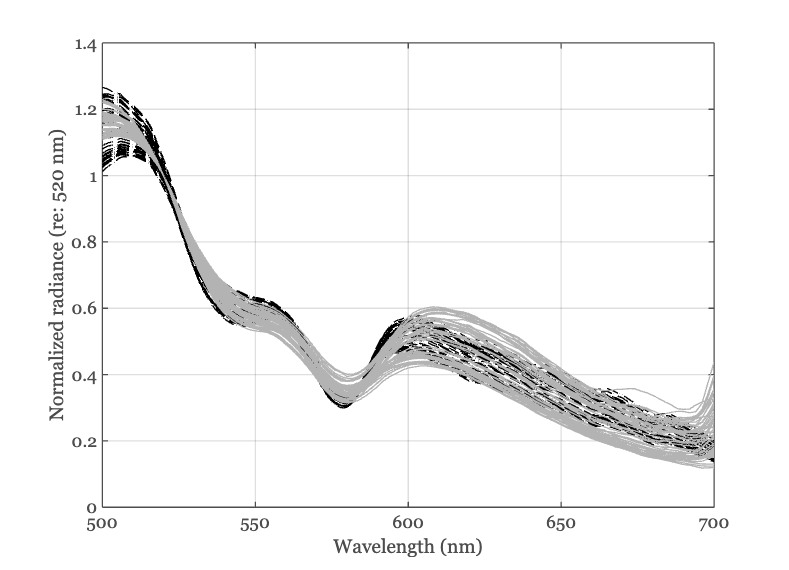

predicted = finalFluorophores*weights;
ieFigure; 
hA = plot(wave,predicted,'k--'); hold on;
hB = plot(wave,lipData,'Color',[1 1 1]*0.7); grid on; xlabel('Wavelength (nm)'); ylabel('Normalized radiance (re: 520 nm)')

Scatter plot to assess precision

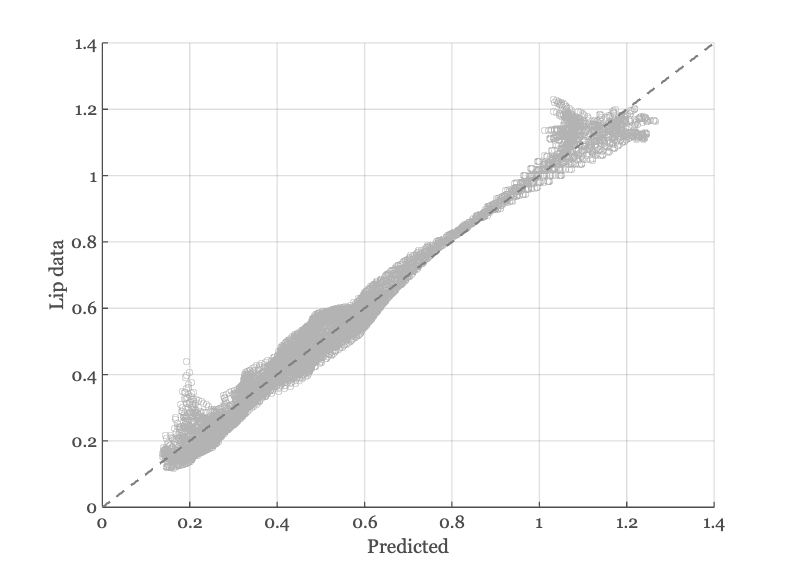

ieFigure;
hScatter = scatter(predicted(:),lipData(:),'o'); 
hScatter.CData = [1 1 1]*0.7;
identityLine; xlabel('Predicted'); ylabel('Lip data');

## Fit the subjects individually

For each subject, the tongue data with 405 and 415.  Use the five fluorophores to fit, adjusting only for the blood.

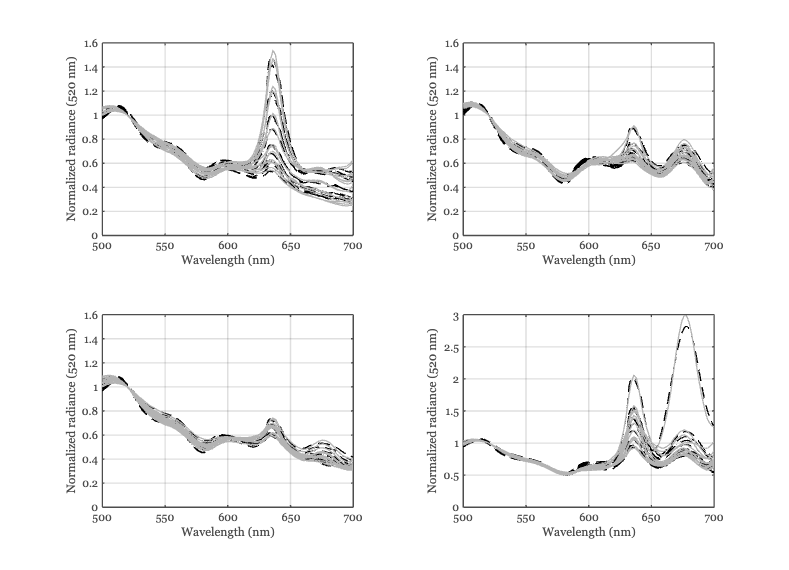

odTongue = zeros(1,numel(subjects));
weights = cell(4,1);
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the tongue data
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

    % Find the blood optical density
    [odTongue(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,tongueData,savedFluorophores);
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,tongueData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance (520 nm)');
    set(gca,'ylim',[0 1.6]);
    if ii==4, set(gca,'ylim',[0 3]); end
end
exportgraphics(gcf,'IndividualFits-tongue.png','Resolution',150);

Table of the tongue weights and blood od

for ii=1:numel(subjects)
    mn = mean(weights{ii},2);
    fprintf('Collagen %.2f FAD %.2f Porphyrin %.2f Chlorophyll %0.2f PseudoKeratin %.2f FAD/Collagen %0.3f\n',mn,mn(2)/mn(1));
end

Collagen 8.69 FAD 0.55 Porphyrin 0.42 Chlorophyll 0.04 PseudoKeratin 0.32 FAD/Collagen 0.064
Collagen 13.18 FAD 0.55 Porphyrin 0.20 Chlorophyll 0.27 PseudoKeratin 0.23 FAD/Collagen 0.042
Collagen 9.23 FAD 0.54 Porphyrin 0.19 Chlorophyll 0.04 PseudoKeratin 0.30 FAD/Collagen 0.058
Collagen 10.72 FAD 0.52 Porphyrin 0.73 Chlorophyll 0.54 PseudoKeratin 0.36 FAD/Collagen 0.049


fprintf('Subjects tongue blood optical densities %.2f\n',odTongue);

Subjects tongue blood optical densities 9.97
Subjects tongue blood optical densities 11.75
Subjects tongue blood optical densities 9.50
Subjects tongue blood optical densities 13.21


## Fit individually again, different excitation light

Now with the 450 nm excitation

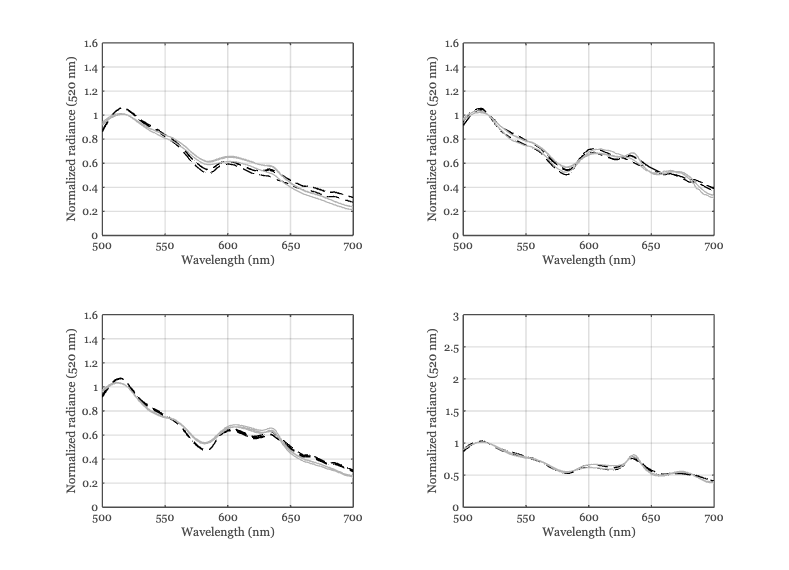

odTongue = zeros(1,numel(subjects));
weights = cell(4,1);
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the tongue data
    tongueFiles450 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',450);
    tongueData  = oeReadFiles(tongueFiles450,'normalized wave',normWave,'wave',wave);

    % Find the blood optical density
    [odTongue(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,tongueData,savedFluorophores);
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,tongueData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance (520 nm)');
    set(gca,'ylim',[0 1.6]);
    if ii==4, set(gca,'ylim',[0 3]); end
end
exportgraphics(gcf,'IndividualFits-tongue450.png','Resolution',150);

### Here is the 450 nm table

for ii=1:numel(subjects)
    mn = mean(weights{ii},2);
    fprintf('Collagen %.2f FAD %.2f Porphyrin %.2f Chlorophyll %0.2f PseudoKeratin %.2f FAD/Collagen %0.3f\n',mn,mn(2)/mn(1));
end

Collagen 8.90 FAD 0.72 Porphyrin 0.05 Chlorophyll 0.00 PseudoKeratin 0.30 FAD/Collagen 0.080
Collagen 12.77 FAD 0.60 Porphyrin 0.06 Chlorophyll 0.02 PseudoKeratin 0.35 FAD/Collagen 0.047
Collagen 13.83 FAD 0.71 Porphyrin 0.09 Chlorophyll 0.00 PseudoKeratin 0.20 FAD/Collagen 0.051
Collagen 10.21 FAD 0.61 Porphyrin 0.24 Chlorophyll 0.09 PseudoKeratin 0.35 FAD/Collagen 0.060


fprintf('Subjects tongue blood optical densities %.2f\n',odTongue);

Subjects tongue blood optical densities 17.26
Subjects tongue blood optical densities 17.66
Subjects tongue blood optical densities 16.80
Subjects tongue blood optical densities 16.69


## Fit the lip data

For the lip, we only fit using the collagen and FAD data, adjusting for the blood.  We omit the porphyrins, chlorophyll and pseudo-keratin.

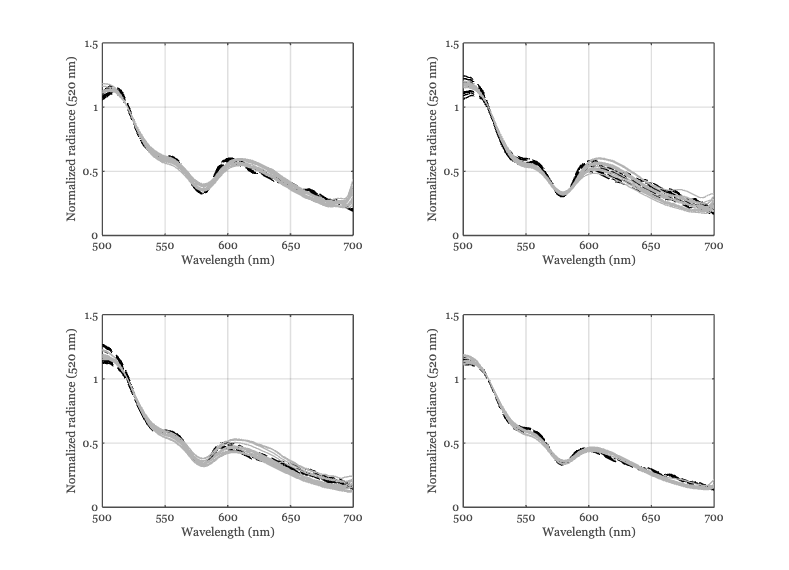

odLip = zeros(1,numel(subjects));
weights = cell(4,1);
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the lip data
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    lipData  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);

    % Find the blood optical density using only the first two columns of
    % saved fluorophores.
    [odLip(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,lipData,savedFluorophores(:,[1,2]));
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,lipData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance (520 nm)');
    set(gca,'ylim',[0 1.5]);
end
exportgraphics(gcf,'IndividualFits-lip.png','Resolution',150);

## Table of the lip weights and blood density

405 nm and 415 nm

for ii=1:numel(subjects)
    mn = mean(weights{ii},2);
    fprintf('Collagen %.2f FAD %.2f FAD/Collagen %.3f\n',mn, mn(2)/mn(1));
end

Collagen 17.34 FAD 0.63 FAD/Collagen 0.036
Collagen 16.12 FAD 0.54 FAD/Collagen 0.033
Collagen 13.12 FAD 0.49 FAD/Collagen 0.038
Collagen 11.81 FAD 0.53 FAD/Collagen 0.045


fprintf('Subjects lip optical densities %.2f\n',odLip);

Subjects lip optical densities 11.54
Subjects lip optical densities 9.13
Subjects lip optical densities 6.32
Subjects lip optical densities 5.97


## Lip with the 450 nm excitation light

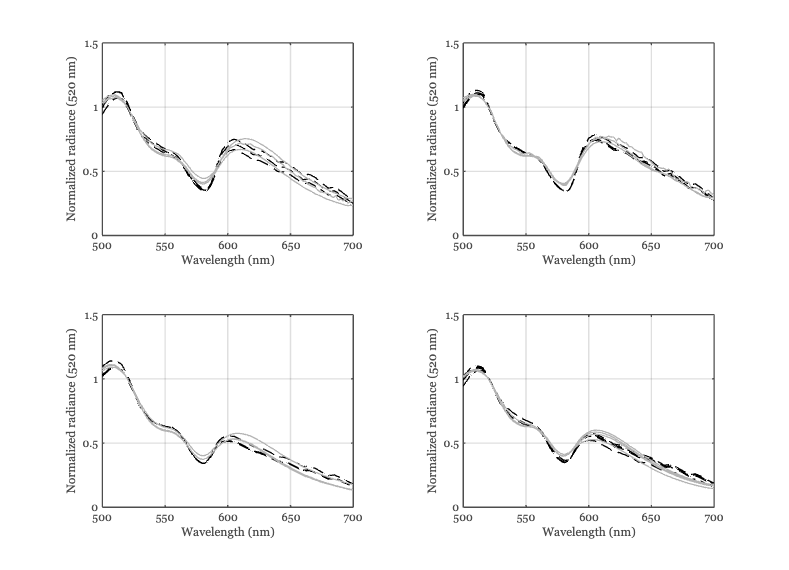

odLip = zeros(1,numel(subjects));
weights = cell(4,1);
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the lip data
    lipFiles450 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',450);
    lipData  = oeReadFiles(lipFiles450,'normalized wave',normWave,'wave',wave);

    % Find the blood optical density using only the first two columns of
    % saved fluorophores.
    [odLip(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,lipData,savedFluorophores(:,[1,2]));
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,lipData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance (520 nm)');
    set(gca,'ylim',[0 1.5]);
end
exportgraphics(gcf,'IndividualFits-lip450.png','Resolution',150);

### Table for 450 nm excitation.

for ii=1:numel(subjects)
    mn = mean(weights{ii},2);
    fprintf('Collagen %.2f FAD %.2f FAD/Collagen %.3f\n',mn, mn(2)/mn(1));
end

Collagen 22.18 FAD 0.75 FAD/Collagen 0.034
Collagen 24.61 FAD 0.73 FAD/Collagen 0.030
Collagen 14.58 FAD 0.66 FAD/Collagen 0.045
Collagen 15.19 FAD 0.72 FAD/Collagen 0.048


fprintf('Subjects lip optical densities %.2f\n',odLip);

Subjects lip optical densities 17.24
Subjects lip optical densities 17.68
Subjects lip optical densities 10.56
Subjects lip optical densities 12.70
